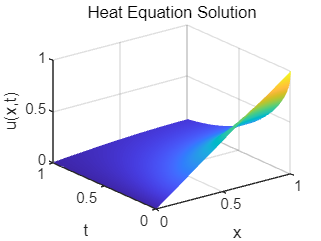

clc; clear; close all;

% 参数
a  = 1;       % 扩散系数 a
L  = 1;       % 区间长度 l
u0 = 1;       % 初始值中的 u0

% 空间与时间离散
x = linspace(0, L, 100);
t = linspace(0, 1, 100);   % 计算到 t=1，可自己改

% pdepe 求解
sol = pdepe(0, @pde, @ic, @bc, x, t);

u = sol(:,:,1);

% 画图
figure;
surf(x, t, u);
xlabel('x'); ylabel('t'); zlabel('u(x,t)');
title('Heat Equation Solution');
shading interp;

% compare_simpson_chebyshev.m
% 比较复合辛普森与 Gauss-Chebyshev 积分（用于积分 ∫_{-1}^1 sqrt(1-x^2) dx）
clear; close all; clc;

% 精确值
I_exact = pi/2;

% 待积函数
f = @(x) sqrt(1 - x.^2);

%% 1) 复合辛普森（Simpson）测试
M_list = [20, 40, 80, 160, 320]; % 每个 M 为划分区间个数（需为偶数）
I_simpson = zeros(size(M_list));
err_simpson = zeros(size(M_list));

for k = 1:length(M_list)
    M = M_list(k);
    if mod(M,2)~=0
        error('Simpson requires even number of subintervals M.');
    end
    a = -1; b = 1;
    h = (b-a)/M;
    x = a:h:b;
    y = f(x);
    % 复合辛普森公式
    S = y(1) + y(end) + 4*sum(y(2:2:end-1)) + 2*sum(y(3:2:end-2));
    I_simpson(k) = S * h/3;
    err_simpson(k) = abs(I_simpson(k) - I_exact);
end

%% 2) Gauss-Chebyshev (题中给出的节点与权重) 测试
N_list = [2, 4, 8, 16, 32, 64]; % 使用的节点数 N
I_cheb = zeros(size(N_list));
err_cheb = zeros(size(N_list));

for k = 1:length(N_list)
    N = N_list(k);
    n = (1:N)'; % n from 1 to N (column)
    x_n = cos(n*pi/(N+1));
    w_n = (pi/(N+1)) .* (sin(n*pi/(N+1))).^2;
    I_cheb(k) = sum(w_n .* f(x_n));
    err_cheb(k) = abs(I_cheb(k) - I_exact);
end

%% 结果输出（表格）
fprintf('复合辛普森 (M)      I_approx           error\n');

复合辛普森 (M)      I_approx           error


for k=1:length(M_list)
    fprintf('M=%4d   %12.10f   %12.4e\n', M_list(k), I_simpson(k), err_simpson(k));
end

M=  20   1.5635040794     7.2922e-03
M=  40   1.5682235321     2.5728e-03
M=  80   1.5698876762     9.0865e-04
M= 160   1.5704752429     3.2108e-04
M= 320   1.5706828371     1.1349e-04


fprintf('\nGauss-Chebyshev (N)  I_approx           error\n');


Gauss-Chebyshev (N)  I_approx           error


for k=1:length(N_list)
    fprintf('N=%4d   %12.10f   %12.4e\n', N_list(k), I_cheb(k), err_cheb(k));
end

N=   2   1.3603495232     2.1045e-01
N=   4   1.3361991651     2.3460e-01
N=   8   1.3335881614     2.3721e-01
N=  16   1.3333529307     2.3744e-01
N=  32   1.3333347053     2.3746e-01
N=  64   1.3333334243     2.3746e-01


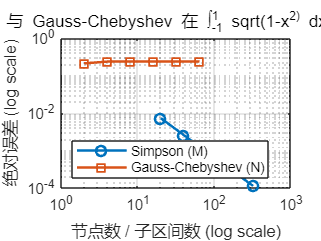


%% 画图：误差收敛（对数坐标）
figure;
loglog(M_list, err_simpson, '-o', 'LineWidth',1.5); hold on;
loglog(N_list, err_cheb, '-s', 'LineWidth',1.5);
grid on;
legend('Simpson (M)', 'Gauss-Chebyshev (N)', 'Location','southwest');
xlabel('节点数 / 子区间数 (log scale)');
ylabel('绝对误差 (log scale)');
title('Simpson 与 Gauss-Chebyshev 在 ∫_{-1}^1 sqrt(1-x^2) dx 的误差比较');

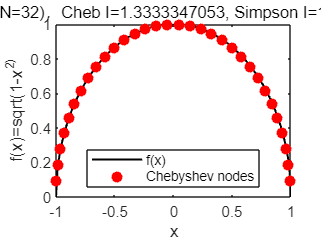


%% 可视化近似值与精确值（以 N=32 为例）
Nvis = 32;
n = (1:Nvis)';
x_n = cos(n*pi/(Nvis+1));
w_n = (pi/(Nvis+1)) .* (sin(n*pi/(Nvis+1))).^2;
I_cheb_vis = sum(w_n .* f(x_n));

Mvis = 160;
a=-1; b=1; h=(b-a)/Mvis; xv=a:h:b;
I_simp_vis = simpson_numeric(f,a,b,Mvis);

figure;
plot(xv, f(xv), 'k-', 'LineWidth',1.2); hold on;
plot(x_n, f(x_n), 'ro', 'MarkerFaceColor','r');
xlabel('x'); ylabel('f(x)=sqrt(1-x^2)');
title(sprintf('函数与 Gauss-Chebyshev 节点 (N=%d)，Cheb I=%.10f, Simpson I=%.10f, exact=%.10f', ...
    Nvis, I_cheb_vis, I_simp_vis, I_exact));
legend('f(x)','Chebyshev nodes','Location','best');


%% 辅助函数：复合辛普森（单独实现以便复用）

function I = simpson_numeric(fun,a,b,M)
    if mod(M,2)~=0
        error('Simpson requires even M');
    end
    h = (b-a)/M;
    x = a:h:b;
    y = fun(x);
    S = y(1) + y(end) + 4*sum(y(2:2:end-1)) + 2*sum(y(3:2:end-2));
    I = S * h/3;
end

function [c,f,s] = pde(x,t,u,ux)
    a = 1;
    c = 1;
    f = a^2 * ux;
    s = 0;
end

%% ---------------- 初始条件 u(x,0)=u0*x/L ----------------
function u0_fun = ic(x)
    u0 = 1;   % 与上面一致
    L  = 1;
    u0_fun = u0 * x / L;
end

%% ---------------- 边界条件 ----------------
% u(0,t)=0  → 左端 Dirichlet
% u_x(L,t)=0 → 右端 Neumann
function [pl,ql,pr,qr] = bc(xl,ul,xr,ur,t)
    pl = ul;     % u(0,t)=0
    ql = 0;

    pr = 0;      % u_x(l,t)=0
    qr = 1;
end

